# Robot PKM

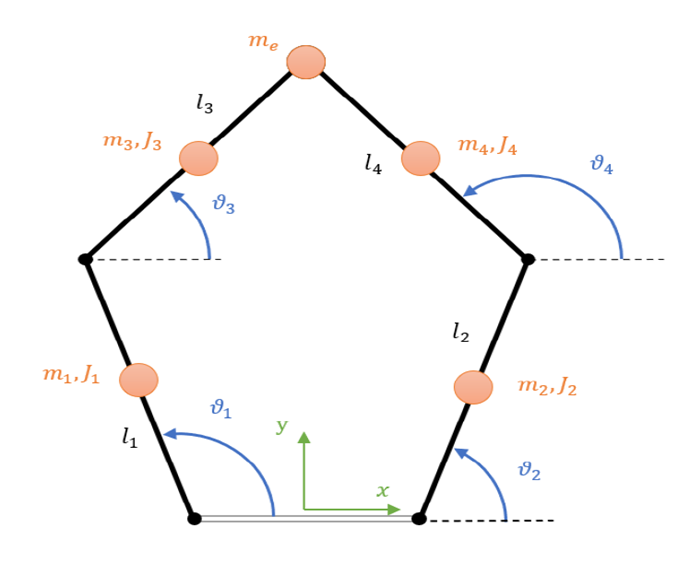

##   Definizione dati e informazioni utili manipolatore 

[PKM] = Define_Robot()

PKM = struct with fields:
    link: [1×1 struct]


PKM = struct with fields:
    link: [1×1 struct]


PKM = struct with fields:
    link: [1×1 struct]
    vite: [1×1 struct]



theta1 = deg2rad(60); % Condizione iniziale posizione Theta1
theta2 = deg2rad(-20); %  Condizione iniziale posizione Theta2
thetaV = deg2rad(720); % Angolo proprio della vite

theta1_p = 0; %  Condizione iniziale velocità theta1
theta2_p = 0; %  Condizione iniziale velocità tehta2
thetaV_p = 0.5; % Velocita thetav di prova

theta1_pp = 0.05; %  Condizione iniziale accelerazione theta1
theta2_pp = 0.05; %  Condizione iniziale accelarazione theta2
thetaV_pp = 0.5; % Accelerazione thetav di prova

Theta = [theta1; theta2; thetaV] % Vettore coordinate posizione iniziale

Theta =     1.0472
   -0.3491
   12.5664


Theta_p = [theta1_p; theta2_p; thetaV_p] % Vettore coordinate velocità iniziale

Theta_p =          0
         0
    0.5000


Theta_pp = [theta1_pp; theta2_pp; thetaV_pp] % Vettore coordinate accelerazione

Theta_pp =     0.0500
    0.0500
    0.5000


## Legge di moto

Ldm_theta = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


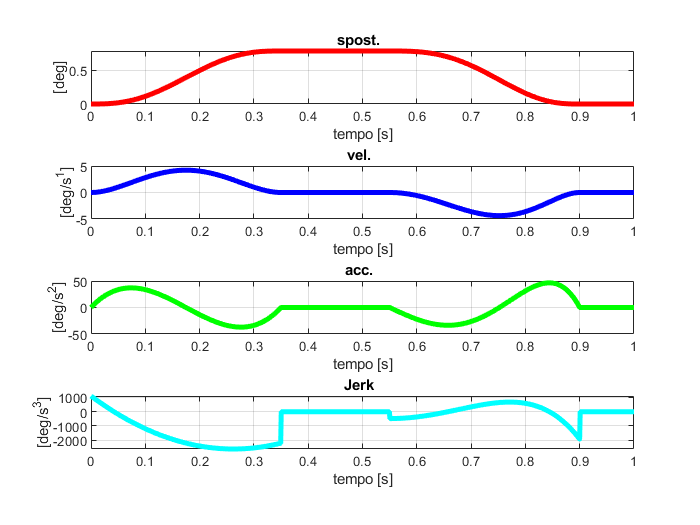

Ldm_theta1 = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta1] = Define_ldm(deg2rad(45)) % Definisce una legge di moto data l'alzata in gradi per theta1

Ldm_theta = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


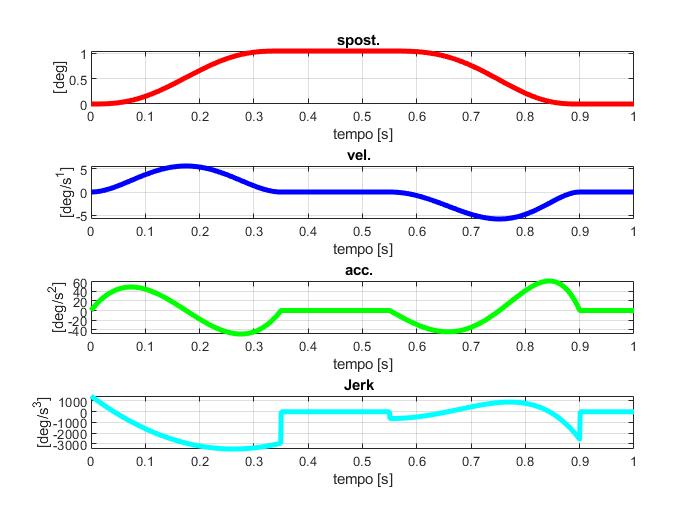

Ldm_theta2 = struct with fields:
    vldm: {4×1 cell}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta2] = Define_ldm(deg2rad(60)) % Definisce una legge di moto data l'alzata in gradi per theta2

Associo a theta1 e theta2 le stesse leggi di moto, ma con valori di angoli di partenza diversi

theta1ldm = theta1 + Ldm_theta1.moto.data{1,1}.v;
theta2ldm = theta2 + Ldm_theta2.moto.data{1,1}.v;

## Cinematica diretta

**Analisi posizione**

[P, theta3, theta4, E1, E2] = Cinematica_Diretta_Posizione_1000(PKM, theta1ldm, theta2ldm, thetaV)

P =     0.2786    0.2786    0.2786    0.2786    0.2786    0.2786    0.2786    0.2786    0.2786    0.2785    0.2785    0.2785    0.2785    0.2785    0.2785    0.2785    0.2784    0.2784    0.2784    0.2784    0.2783    0.2783    0.2782    0.2782    0.2781    0.2781    0.2780    0.2780    0.2779    0.2778    0.2778    0.2777    0.2776    0.2775    0.2774    0.2773    0.2772    0.2771    0.2770    0.2769    0.2767    0.2766    0.2765    0.2763    0.2762    0.2760    0.2758    0.2757    0.2755    0.2753
    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1603    0.1603    0.1603    0.1603    0.1604    0.1604    0.1605    0.1605    0.1606    0.1606    0.1607    0.1607    0.1608    0.1609    0.1610    0.1611    0.1612    0.1613    0.1614    0.1615    0.1616    0.1617    0.1619    0.1620    0.1622    0.1623    0.1625    0.1627    0.1629    0.1630    0.1632    0.1634    0.1637    0.1639    0.1641    0.1643    0

theta3 =    -0.2273   -0.2273   -0.2273   -0.2273   -0.2273   -0.2273   -0.2273   -0.2273   -0.2273   -0.2273   -0.2272   -0.2272   -0.2272   -0.2271   -0.2271   -0.2270   -0.2270   -0.2269   -0.2268   -0.2267   -0.2266   -0.2265   -0.2264   -0.2262   -0.2261   -0.2260   -0.2258   -0.2256   -0.2254   -0.2252   -0.2250   -0.2248   -0.2245   -0.2243   -0.2240   -0.2237   -0.2234   -0.2231   -0.2227   -0.2224   -0.2220   -0.2216   -0.2212   -0.2208   -0.2204   -0.2199   -0.2195   -0.2190   -0.2185   -0.2180


theta4 =     1.7573    1.7573    1.7573    1.7573    1.7573    1.7573    1.7573    1.7574    1.7574    1.7575    1.7575    1.7576    1.7577    1.7578    1.7579    1.7580    1.7582    1.7583    1.7585    1.7587    1.7589    1.7592    1.7595    1.7598    1.7601    1.7604    1.7608    1.7612    1.7616    1.7621    1.7626    1.7631    1.7637    1.7643    1.7649    1.7655    1.7662    1.7669    1.7677    1.7685    1.7693    1.7701    1.7710    1.7720    1.7729    1.7739    1.7750    1.7761    1.7772    1.7784


E1 =     0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0350    0.0349    0.0349    0.0349    0.0349    0.0349    0.0348    0.0348    0.0348    0.0347    0.0347    0.0347    0.0346    0.0346    0.0345    0.0344    0.0344    0.0343    0.0342    0.0341    0.0341    0.0340    0.0339    0.0338    0.0337    0.0335    0.0334    0.0333    0.0332    0.0330    0.0329    0.0327    0.0326    0.0324    0.0322    0.0320    0.0318    0.0316    0.0314    0.0312
    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2167    0.2167    0.2167    0.2167    0.2168    0.2168    0.2168    0.2169    0.2169    0.2170    0.2170    0.2170    0.2171    0.2172    0.2172    0.2173    0.2173    0.2174    0.2175    0.2176    0.2176    0.2177    0.2178    0.2179    0.2180    0.2181    0.2182    0.2183    0.2184    0.2185    

E2 =     0.3249    0.3249    0.3249    0.3249    0.3249    0.3249    0.3249    0.3249    0.3249    0.3249    0.3249    0.3249    0.3250    0.3250    0.3250    0.3250    0.3250    0.3250    0.3250    0.3251    0.3251    0.3251    0.3251    0.3252    0.3252    0.3252    0.3252    0.3253    0.3253    0.3254    0.3254    0.3255    0.3255    0.3256    0.3256    0.3257    0.3257    0.3258    0.3259    0.3259    0.3260    0.3261    0.3262    0.3263    0.3264    0.3264    0.3265    0.3266    0.3267    0.3268
   -0.0855   -0.0855   -0.0855   -0.0855   -0.0855   -0.0855   -0.0855   -0.0855   -0.0855   -0.0855   -0.0854   -0.0854   -0.0854   -0.0854   -0.0854   -0.0853   -0.0853   -0.0852   -0.0852   -0.0851   -0.0851   -0.0850   -0.0849   -0.0849   -0.0848   -0.0847   -0.0846   -0.0845   -0.0844   -0.0843   -0.0841   -0.0840   -0.0839   -0.0837   -0.0836   -0.0834   -0.0832   -0.0830   -0.0828   -0.0826   -0.0824   -0.0822   -0.0820   -0.0817   -0.0815   -0.0812   -0.0809   -0.0807   -0.0804   -

x = P(1,1);
y = P(2,1);
z = P(3,1);

**Rappresentazione grafica**

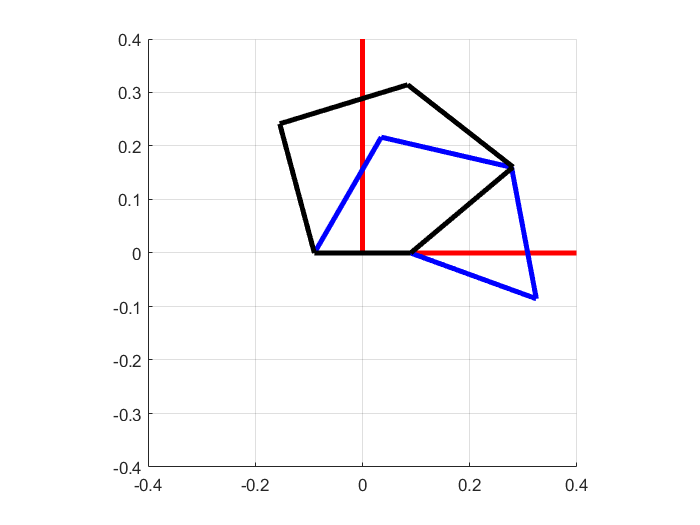

O = [0 0 0]'; A = eye(3,3); color0 = ['r', 'r', 'r']; % Origine sistema di riferimento
H1 = [-d; 0; 0]; % Coordinate punto H1
H2 = [d; 0; 0]; % Coordinate punto H2

figure;
axis equal
Draw_assi(O, A, color0)
Draw_Link3D(O, H1, H2, E1(:,1), E2(:,1), P(:,1),'b')
Draw_Link3D(O, H1, H2, E1(:,400), E2(:,400), P(:,400),'k')

xlim([-0.4 0.4])
ylim([-0.4 0.4])
zlim([-0.5 0.5])

view([-0.50 90.000])

**Analisi velocità**

% si procede ora al calcolo di x_dot e y_dot
N11 = -x*y*sin(theta1)+ x*l^2*sin(theta1)*sin(theta2)+y^2*l*cos(theta1)-y*l^2*cos(theta1)*sin(theta2) - ...
    y*l*d*sin(theta1)+d*l^2*sin(theta1)*sin(theta2);

N12 = x*y*l*sin(theta2)-x*l^2*sin(theta2)*sin(theta1)-y^2*l*cos(theta2)+y*l^2*sin(theta1)*cos(theta2) - ...
    y*l*d*sin(theta2)+d*l^2*sin(theta2)*sin(theta1);

D1 = l*x*(sin(theta1)-sin(theta2))+ l*y*(cos(theta2)-cos(theta1))+l^2*sin(theta2-theta1)-l*d*(sin(theta1)+sin(theta2));

D2 = D1*(y-l*sin(theta2));

N21 = -x*N11+d*N11+N11*l*cos(theta2);

N22 = -x*N12+d*N12+N12*l*cos(theta2)-D1*x*l*sin(theta2)+y*D1*l*cos(theta2)+D1*d*l*sin(theta2);

x_p = (N11*theta1_p + N12*theta2_p)/D1;
y_p = (theta1_p*(-x*N11+d*N11+N11*l*cos(theta2))+theta2_p*(-x*N12+d*N12+N12*l*cos(theta2)-D1*x*l*sin(theta2)+y*D1*l*cos(theta2)+D1*d*l*sin(theta2)))/D2;
z_p = pv/(2*pi)*thetaV_p;

P_p = [x_p; y_p; z_p]

P_p =          0
         0
    0.0016


**Definizione della Jacobiana per analisi velocità**

J = [N11/D1, N12/D1, 0;
     N21/D2, N22/D2, 0;
     0, 0, pv/(2*pi)]

J =    -1.5377    0.1067         0
   -0.2902    0.2389         0
         0         0    0.0032



P_pProva = J*Theta_p

P_pProva =          0
         0
    0.0016


**Analisi accelerazione**

N11_p = -x_p*y*sin(theta1) - x*y_p*sin(theta1) - x*y*cos(theta1)*theta1_p + x_p*l^2*sin(theta1)*sin(theta2) + ...
    + x_p*l^2*cos(theta1)*theta1_p*sin(theta2) + z*l^2*sin(theta1)*cos(theta2)*theta2_p + 2*y*y_p*l*cos(theta1) - ...
    y^2*l*sin(theta1)*theta1_p - y_p*l^2*cos(theta1)*sin(theta2) + y*l^2*sin(theta1)*theta1_p*sin(theta2) - ...
    y*l^2*cos(theta1)*cos(theta2)*theta2_p - y_p*l*d*sin(theta1) - y*l*d*cos(theta1)*theta1_p + ...
    d*l^2*cos(theta1)*theta1_p*sin(theta2) + d*l^2*sin(theta1)*cos(theta2)*theta2_p;

D1_p = l*x_p*(sin(theta1)-sin(theta2)) + l*x*(cos(theta1)*theta1_p - cos(theta2)*theta2_p) + ...
    l*y_p*(cos(theta2)-cos(theta1)) - l*y*(sin(theta2)*theta2_p - sin(theta1)*theta1_p) - ...
    l^2*cos(theta2-theta1)*(theta2_p-theta1_p) - l*d*(cos(theta1)*theta1_p + cos(theta2)*theta2_p);

N12_p = x_p*y*l*sin(theta2) + x*y_p*l*sin(theta2) + x*y*l*cos(theta2)*theta2_p - x_p*l^2*sin(theta2)*sin(theta1) - ...
    x*l^2*cos(theta2)*theta2_p*sin(theta1) - x*l^2*sin(theta2)*cos(theta1)*theta1_p - 2*y*y_p*l*cos(theta2) + ...
    y^2*l*sin(theta2)*theta2_p + y_p*l^2*sin(theta1)*cos(theta2) + y*l^2*cos(theta1)*theta1_p*cos(theta2) - ...
    y*l^2*sin(theta1)*sin(theta2)*theta2_p - y_p*l*d*sin(theta2) - y*l*d*cos(theta2)*theta2_p + ...
    d*l^2*cos(theta2)*theta2_p*sin(theta1) + d*l^2*sin(theta2)*cos(theta1)*theta1_p;

N21_p = -x_p*N11 - x*N11_p + d*N11_p + l*cos(theta2)*N11_p - l*sin(theta2)*theta2_p*N11;

D2_p = D1_p*(y - l*sin(theta2)) + D1*(y_p - l*cos(theta2)*theta2_p);

N22_p = -x_p*N12 - x*N12_p + d*N12_p + N12_p*l*cos(theta2) - N12*l*sin(theta2)*theta2_p - D1_p*x*l*sin(theta2) - ...
    D1*x_p*l*sin(theta2) - D1*x*l*cos(theta2)*theta2_p + y_p*D1*l*cos(theta2) + y*D1_p*l*cos(theta2) - ...
    y*D1*l*sin(theta2)*theta2_p + D1_p*d*l*sin(theta2) + D1*d*l*cos(theta2)*theta2_p;

J_p = [(N11_p*D1-N11*D1_p)/D1^2, (N12_p*D1-N12*D1_p)/D1^2, 0;
         (N21_p*D2-N21*D2_p)/D2^2, (N22_p*D2-N22*D2_p)/D2^2, 0;
         0, 0, pv/(2*pi)]

J_p =          0         0         0
         0         0         0
         0         0    0.0032



P_pp = J*Theta_pp + J_p*Theta_p

P_pp =    -0.0716
   -0.0026
    0.0032


x_pp = P_pp(1,1);
y_pp = P_pp(2,1);
z_pp = P_pp(3,1);

## **Cinematica inversa**

**Analisi posizione**

p = 2*d*l + 2*x*l;
e = 2*y*l;
f = x^2 +d^2 +y^2 +2*x*d;
theta1inv = 2*atan2(e + sqrt(p^2 + e^2 -f^2), p +f)

theta1inv = 1.0472

% theta1inv = 2*atan2(e - sqrt(d^2 + e^2 -f^2), d +f)

a = -2*d*l + 2*x*l;
b = +2*y*l;
c = x^2 +d^2 +y^2 -2*x*d;
% theta2inv = 2*atan2(b + sqrt(a^2 + b^2 -c^2), a +c)
theta2inv = 2*atan2(b - sqrt(a^2 + b^2 -c^2), a +c)

theta2inv = -0.3491

**Analisi velocità**

% Si può procedere per la cinematica inversa direttamente invertendo lo Jacobiano opppure lo si può approssimare:
Jinv = J^-1

Jinv =    -0.7101    0.3170         0
   -0.8625    4.5706         0
         0         0  314.1593


Japprox = (J'*J)^-1*J'

Japprox =    -0.7101    0.3170         0
   -0.8625    4.5706         0
         0         0  314.1593


% Nella cinematica inversa dobbiamo trovare gli angoli per far questo facciamo:
Theta_p_inv = Jinv*P_p

Theta_p_inv =          0
         0
    0.5000


**Analisi accelerazione**

Theta_pp_inv = Jinv*(P_pp - J_p*Theta_p);


## Dinamica del sistema

% % Legge dinamica: M(thetaTot)*accT +
% % C(thetaTot,theta_dotTot)*velT+G(thetaTot) = TauT-TauD
% 
% % M -> matrice delle inerzie
% % C -> matrice delle forze centrifughe e di Coriolis
% % G -> forze di gravità
% % TauT -> forze generiche, in questo caso [C1,C2]
% % TauD -> disturbi
% tau1 = 0.5;
% tau2 = 0.5;
% Ilink = 5.22*10^-2; % inerzia link robot |kg*m^2|
% poscm = 0.125; % posizione centro di massa dei link |m|
% mlink = 2.9; % massa link |kg|
% Imat = [Ilink,Ilink^2,Ilink^2,Ilink^2;Ilink^2,Ilink,Ilink^2,Ilink^2;Ilink^2,Ilink^2,Ilink,Ilink^2;Ilink^2,Ilink^2,Ilink^2,Ilink]
% % Dichiarazione delle matrici
% TauT = [tau1, tau2]';
% % Andiamo ad utilizzare la formulazione di lagrane PLV
% % Troviamo l'energia cinetica del link i-esimo
% vc = [1,1]';
% ac = [1,1]';
% % Energia cinetica
% K1 = 1/2*(mlink*(vc')*vc+ac'*Ilink*ac)
% % Serve jacobiana di V e Omega
% M = 4*(mlink*(J')*J+(J_p')*Ilink*J_p)
% K = 0.5*Theta_p'*M*Theta_p
% g = 9.81;
% G = -J*[mlink*g;mlink*g;mlink*g;mlink*g]
% % Dobbiamo definire la jacobiana dell'end-effector
% % J vel J_p acc?
% 
% 